% import files
folder = uigetdir;
path2Files= fullfile(folder,'*.mp3');
contents = dir(path2Files);

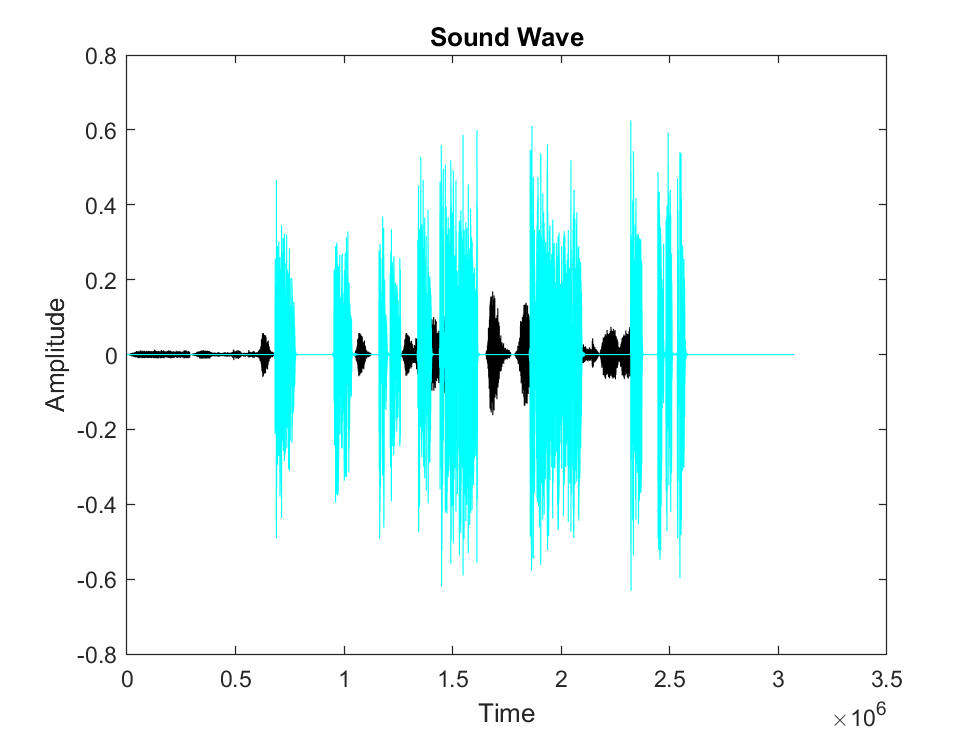

pitchPlot=figure(1);
intensityPlot=figure(2);
ampPlot = figure(3);
    
for i=1:numel(contents)
    file = fullfile(folder, contents(i).name);
    ampPlotting(file,i);
    hold on 
end
ylabel('Amplitude');
xlabel('Time');
title('Sound Wave');
hold off

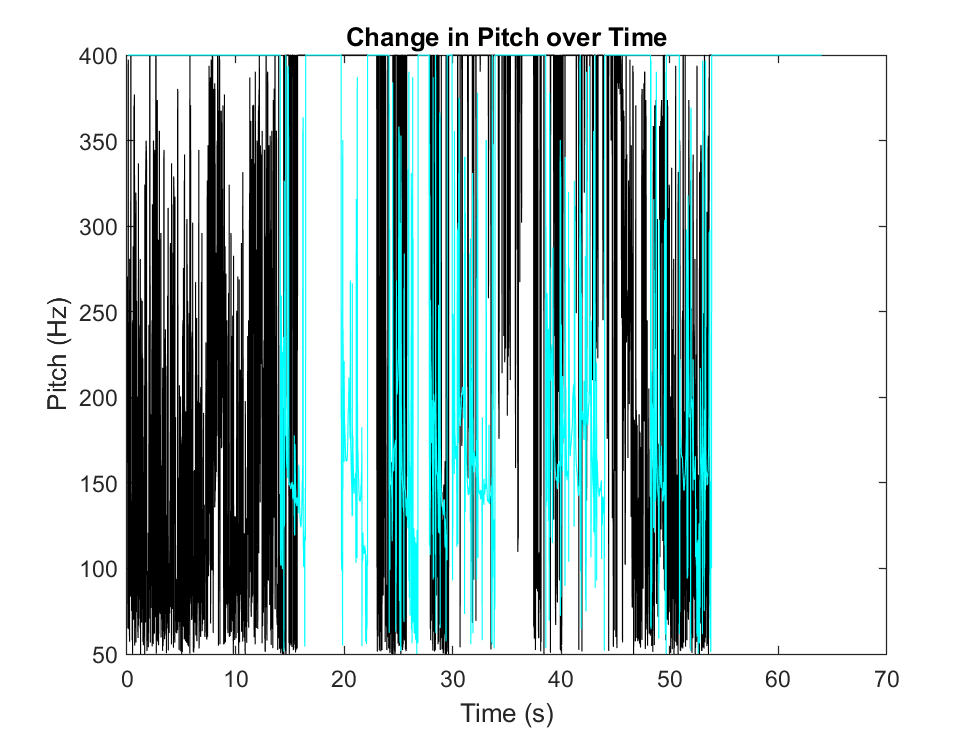


for i=1:numel(contents)
    file = fullfile(folder, contents(i).name);
    pitchPlotting(file,i); 
    hold on
end
ylabel('Pitch (Hz)');
xlabel('Time (s)');
title('Change in Pitch over Time');
hold off

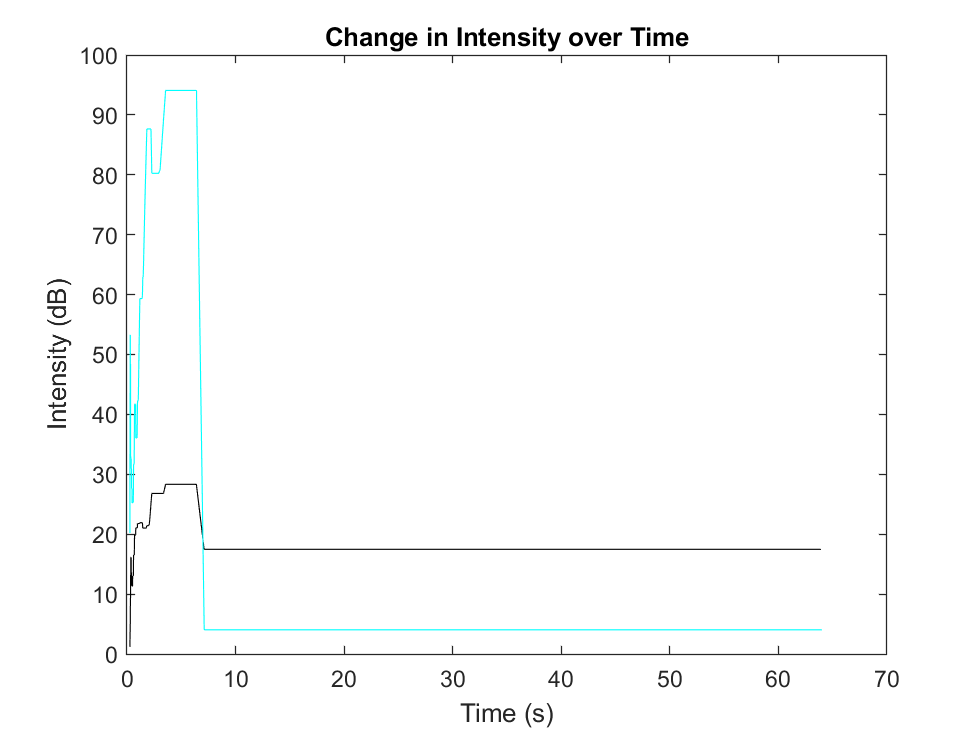


for i=1:numel(contents)
    file = fullfile(folder, contents(i).name);
    intensityPlotting(file,i);
    hold on
end
ylabel('Intensity (dB)');
xlabel('Time (s)');
title('Change in Intensity over Time');
hold off


%create name for dif plots via time stamp
timeStamp = datestr(now);
timeStamp = erase(timeStamp,":");
timeStamp = erase(timeStamp,"-");
pitchName=append('pitchPlot', timeStamp,'.png');
volName=append('intensityPlot', timeStamp,'.png');
ampName=append('ampPlot', timeStamp,'.png');


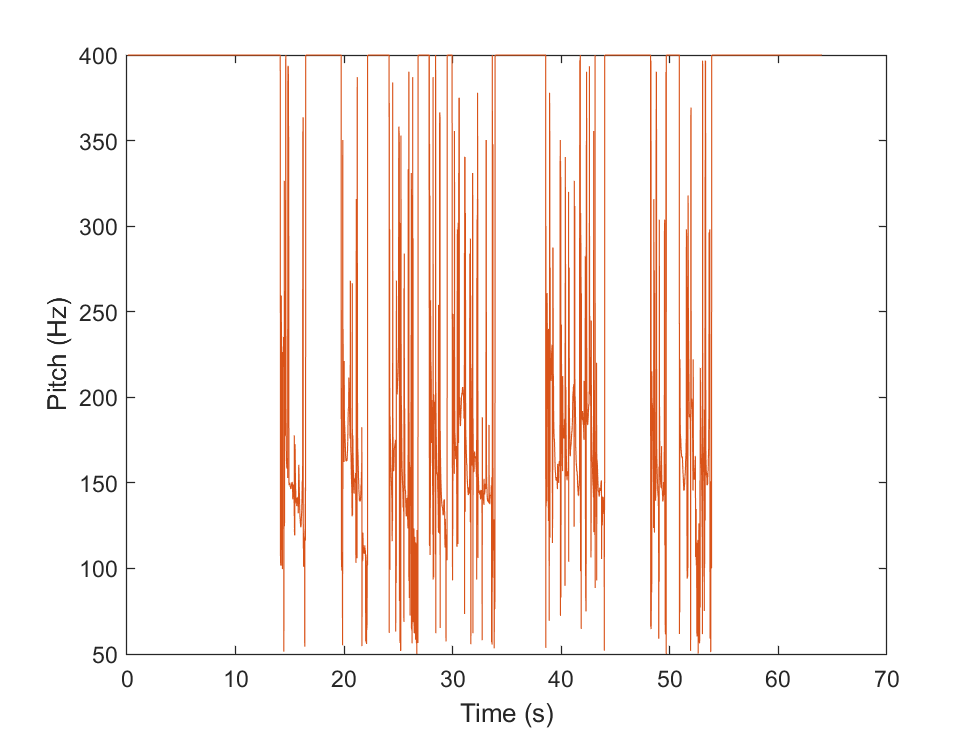

%export as png for site
exportgraphics(figure(1),pitchName);

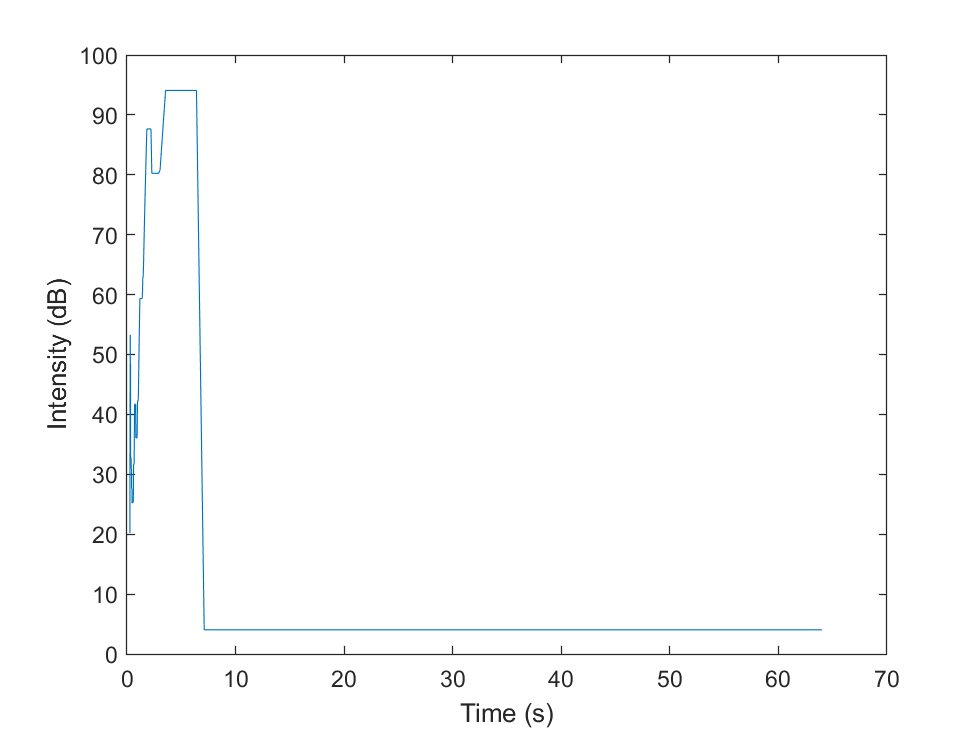

exportgraphics(figure(2),volName);
exportgraphics(figure(2),ampName);

function intensityPlotting(filename,n)
    % read file and store info
    [audioIn,fs] = audioread(filename);
    lenAud = length(audioIn)./fs;
    % pull intensity in sones
    [~,volSones] = acousticLoudness(audioIn,fs,'SoundField','diffuse','TimeVarying',false);
    %convert to form sones to  dB
    voldB= volSones(:,:,1) .* 28;;
    %convert from Barcbins to time
    time = lenAud./[1:1:240];
    % plot
    col= ['k','c', 'm', 'g', 'b', 'r'];
    plot(time,voldB, 'Color', col(n));
end    
    
function pitchPlotting(filename,n)
    % read file and store info
    [audioIn,fs] = audioread(filename);    
    % pull pitch in hertz
    [hz,idx] = pitch(audioIn,fs);
    %samples to time
    time = idx/fs;
    % plot
    col= ['k','c', 'm', 'g', 'b', 'r'];
    plot(time,hz, 'Color', col(n));
end
 
function ampPlotting(filename,n)
    % read file and store info
    [audioIn,fs] = audioread(filename);
    %plot
    col= ['k','c', 'm', 'g', 'b', 'r'];
    plot(audioIn, 'Color', col(n));
end